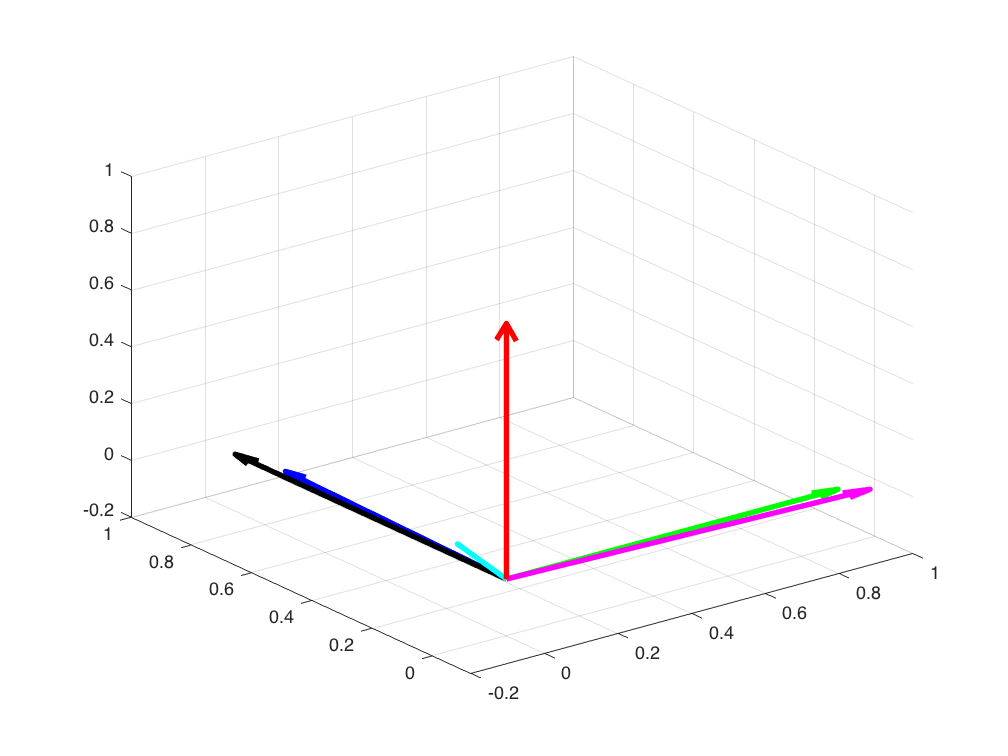

clear 
clc


%Vectores unitarios ortonomales del plano carteciano 
i = [1 0 0];
j = [0 1 0];
k = [0 0 1];

%Visualización de los vectores ortonormales 
figure 
q1 = quiver3(0,0,0,i(1),i(2),i(3),'g');
hold on 
q2 = quiver3(0,0,0,j(1),j(2),j(3),'k');
hold on 
q3 = quiver3(0,0,0,k(1),k(2),k(3),'r');

q1.LineWidth = 3;
q2.LineWidth = 3;
q3.LineWidth = 3;

matrizVectores = [0.1389 0.9889 -0.0526; 0.9844 -0.1320 0.1164; -0.1082 0.0680 0.09918];

vector1 = matrizVectores(:,1);
vector2 = matrizVectores(:,2);
vector3 = matrizVectores(:,3);

hold on 
v1 = quiver3(0,0,0,matrizVectores(1,1),matrizVectores(2,1),matrizVectores(3,1),'b');
hold on 
v2 = quiver3(0,0,0,matrizVectores(1,2),matrizVectores(2,2),matrizVectores(3,2),'m');
hold on 
v3 = quiver3(0,0,0,matrizVectores(1,3),matrizVectores(2,3),matrizVectores(3,3),'c');

v1.LineWidth = 3;
v2.LineWidth = 3;
v3.LineWidth = 3;


angulos = uv2phitheta([vector1(1);vector1(2)])

angulos =    81.9685
   83.8001


angulosphitheta = azel2phitheta([vector1(1);vector1(2)])

angulosphitheta =    81.9693
    0.9942



angulodei = azel2phitheta([i(1);i(2)])

angulodei =          0
    1.0000


angulodeiuv = uv2phitheta([i(1);i(2)])

angulodeiuv =      0
    90


In radar applications, it is often useful to parameterize the hemisphere x ≥ 0 using coordinates denoted by *u* and *v*.

- To convert the φ/θ representation to and from the corresponding *u*/*v* representation, use coordinate conversion functions [`phitheta2uv`](https://www.mathworks.com/help/phased/ref/phitheta2uv.html) and [`uv2phitheta`](https://www.mathworks.com/help/phased/ref/uv2phitheta.html).

- To convert the azimuth/elevation representation to and from the corresponding *u*/*v* representation, use coordinate conversion functions [`azel2uv`](https://www.mathworks.com/help/phased/ref/azel2uv.html) and [`uv2azel`](https://www.mathworks.com/help/phased/ref/uv2azel.html).

You can define *u* and *v* in terms of φ and θ:

*u*=sin*θ*cos*ϕ**v*=sin*θ*sin*ϕ*

In these expressions, φ and θ are the phi and theta angles, respectively.

To convert azimuth and elevation to *u* and *v* use the transformation

*u*=cos*e**l*sin*a**z**v*=sin*e**l*

which is valid only in the range *abs(az)≤=90*.

The values of *u* and *v* satisfy the inequalities

−1≤*u*≤1−1≤*v*≤1*u*2+*v*2≤1

Conversely, the phi and theta angles can be written in terms of *u* and *v* using

tan*ϕ*=*v*/*u*sin*θ*=G*u*2+*v*2

The azimuth and elevation angles can also be written in terms of *u* and *v*:

sin*e**l*=*v*tan*a**z*=*u*G1−*u*2−*v*2

**Conversion between Rectangular and Spherical Coordinates**

The following equations define the relationships between rectangular coordinates and the (*az*,*el*,*R*) representation used in Phased Array System Toolbox software.

To convert rectangular coordinates to (*az*,*el*,*R*):

*R*=G*x*2+*y*2+*z*2*a**z*=tan−1(*y*/*x*)*e**l*=tan−1(*z*/G*x*2+*y*2)

To convert (*az*,*el*,*R*) to rectangular coordinates:

*x*=*R*cos(*e**l*)cos(*a**z*)*y*=*R*cos(*e**l*)sin(*a**z*)*z*=*R*sin(*e**l*)

% Matriz de rotación 
MatrizRotacion = []